# Test for FEEdgeDetection Alg

load('hyd.mat')

st = SimpleTrainingStack({@MultisensorExtractor, @Pearson, @NumFeatRanking, @LDAMahalClassifier}, ...
                {{@StatisticalMomentsAutoSec}, {500}, {}, {}});
stALA = SimpleTrainingStack({@MultisensorExtractor, @Pearson, @NumFeatRanking, @LDAMahalClassifier}, ...
                {{@ALAExtractor}, {500}, {}, {}});
stALAE = SimpleTrainingStack({@MultisensorExtractor, @Pearson, @NumFeatRanking, @LDAMahalClassifier}, ...
                {{@ALAExtractorExtend}, {500}, {}, {}});

## Test With hyd data

targetNum = 3;
cv = cvpartition(profile(:,targetNum),"KFold",10);
%usedSensor = [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24];
usedSensor = [7];% Bei nur Sensor 7 sind die erweitererten Modelle besser

predALA = zeros(size(profile,1),1);
tic
for i = 1:10
    stALA.train(cellfun(@(a) a(cv.training(i),:),sensors(1,usedSensor), 'UniformOutput', false),profile(cv.training(i),targetNum));
    predALA(cv.test(i)) = stALA.apply(cellfun(@(a) a(cv.test(i),:),sensors(1,usedSensor), 'UniformOutput', false));
end
toc

Elapsed time is 23.800825 seconds.


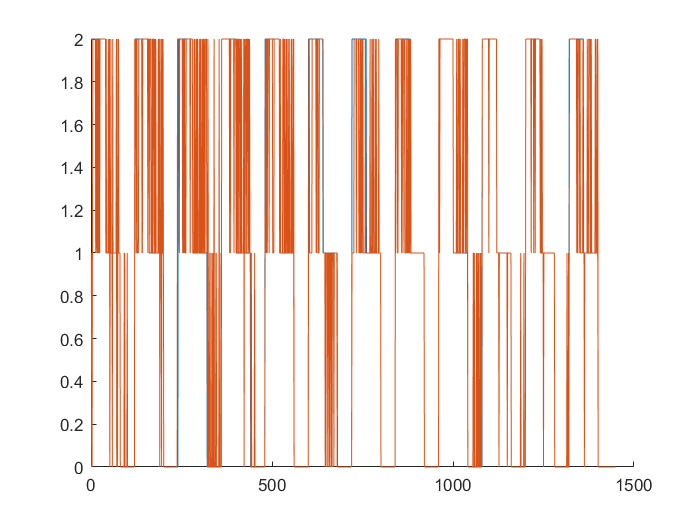




figure()
hold on
plot(profile(:,targetNum))
plot(predALA)


disp("ALA")

ALA


disp(ClassificationError.loss(predALA,profile(:,targetNum)))

   18.9786



pred = zeros(size(profile,1),1);
tic
for i = 1:10
    st.train(cellfun(@(a) a(cv.training(i),:),sensors(1,usedSensor), 'UniformOutput', false),profile(cv.training(i),targetNum));
    pred(cv.test(i)) = st.apply(cellfun(@(a) a(cv.test(i),:),sensors(1,usedSensor), 'UniformOutput', false));
end
toc

Elapsed time is 27.814858 seconds.


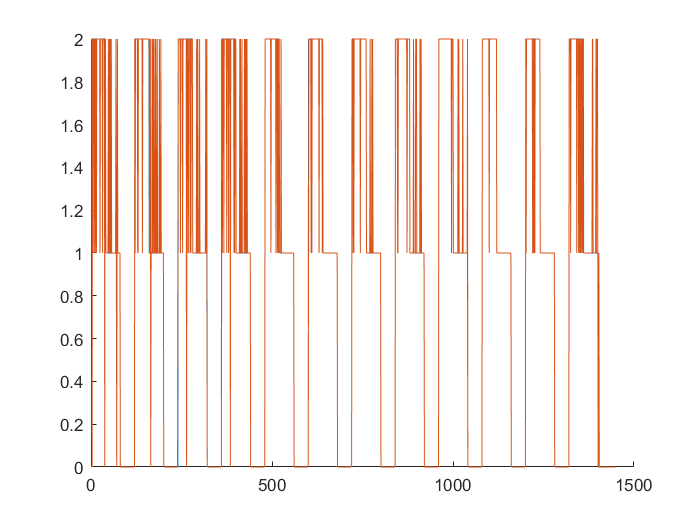

%st.show();
figure()
hold on
plot(profile(:,targetNum))
plot(pred)


disp("Edge")

Edge


disp(ClassificationError.loss(pred,profile(:,targetNum)))

    7.6605



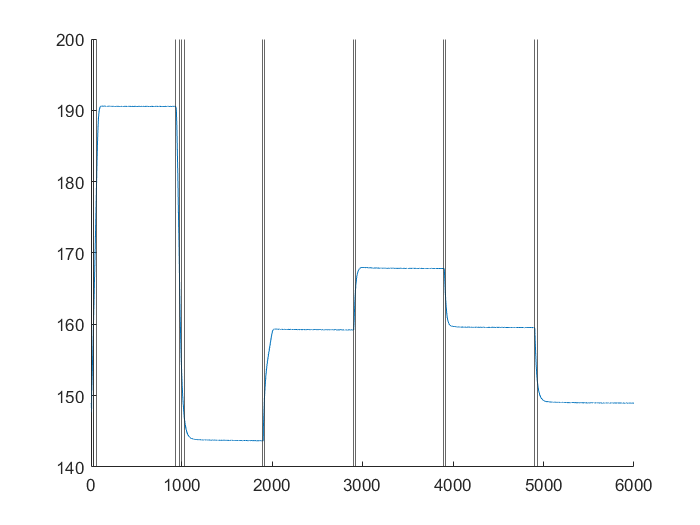


for i = 1:size(st.obj{1,1}.extractors,2)
    figure()
    hold on
    plot(mean(sensors{1,usedSensor(i)},1))
    for j = 1:size(st.obj{1,1}.extractors{i}.segStart,2)
        xline(st.obj{1,1}.extractors{i}.segStart(j))
        xline(st.obj{1,1}.extractors{i}.segStop(j))
    end
end

if(st.obj{1,2}.nFeat == 112)
    disp('Ok')
else
    disp('error')
end

Ok


predALAE = zeros(size(profile,1),1);
tic
for i = 1:10
    stALAE.train(cellfun(@(a) a(cv.training(i),:),sensors(1,usedSensor), 'UniformOutput', false),profile(cv.training(i),targetNum));
    predALAE(cv.test(i)) = stALAE.apply(cellfun(@(a) a(cv.test(i),:),sensors(1,usedSensor), 'UniformOutput', false));
end
toc

Elapsed time is 30.749583 seconds.


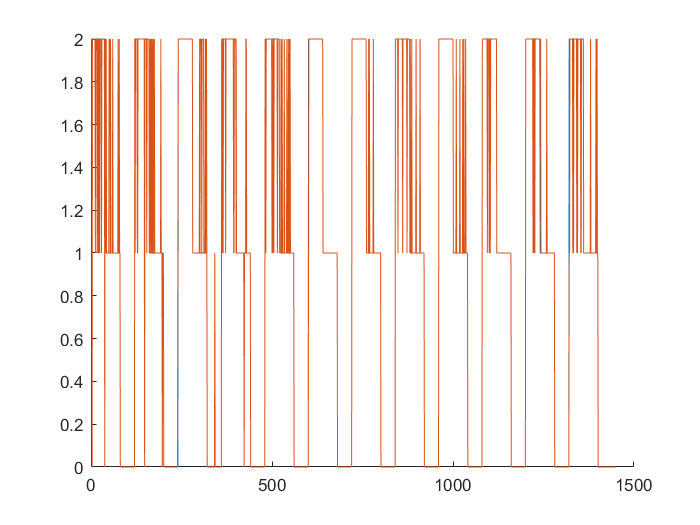

figure()
hold on
plot(profile(:,targetNum))
plot(predALAE)

disp("ALAE")

ALAE


disp(ClassificationError.loss(predALAE,profile(:,targetNum)))

    7.2464



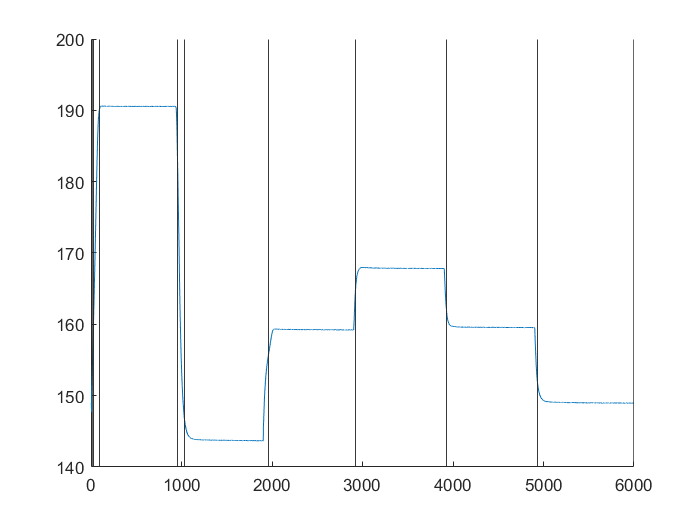


for i = 1:size(stALAE.obj{1,1}.extractors,2)
    figure()
    hold on
    plot(mean(sensors{1,usedSensor(i)},1))
    for j = 1:size(stALAE.obj{1,1}.extractors{i}.start,2)
        xline(stALAE.obj{1,1}.extractors{i}.start(j)*stALAE.obj{1,1}.extractors{i}.dsFactor)
        xline(stALAE.obj{1,1}.extractors{i}.stop(j)*stALAE.obj{1,1}.extractors{i}.dsFactor)
    end
end

if(stALAE.obj{1,2}.nFeat == 72)
    disp('Ok')
else
    disp('error')
end

Ok


## Time estimate

targetNum = 3;

edgeTest = StatisticalMomentsAutoSec();
alaTest = ALAExtractor();
disp("Edge")

Edge


tic
edgeTest.train(sensors{1,7});
testE = edgeTest.apply(sensors{1,7});
toc

Elapsed time is 0.899137 seconds.


disp("ALA")

ALA


tic
alaTest.train(sensors{1,7});
testA = alaTest.apply(sensors{1,7});
toc

Elapsed time is 2.419893 seconds.



numE = NumFeatRanking();
numA = NumFeatRanking();
disp("Edge Num")

Edge Num


tic
numE.train(testE,profile(:,targetNum));
numEF = numE.apply(testE);
toc

Elapsed time is 0.149125 seconds.


disp("ALA Num")

ALA Num


tic
numA.train(testA,profile(:,targetNum));
numAF = numA.apply(testA);
toc

Elapsed time is 0.091123 seconds.



ldaE = LDAMahalClassifier();
ldaA = LDAMahalClassifier();

disp("Edge lda")

Edge lda


tic
ldaE.train(numEF,profile(:,targetNum));
ldaPE = ldaE.apply(numEF);
toc

Elapsed time is 0.011403 seconds.


disp("ALA lda")

ALA lda


tic
ldaA.train(numAF,profile(:,targetNum));
ldaPA = ldaA.apply(numAF);
toc

Elapsed time is 0.006147 seconds.


## Test With voc data

load('daten_old.mat');
d = 1;

sgp30_3_old = validDataFull_old{d,1}{1,1}(validMeasurement_old{d,1}>7,:);
sgp30_2_old = validDataFull_old{d,1}{1,2}(validMeasurement_old{d,1}>7,:);
sgp30_1_old = validDataFull_old{d,1}{1,3}(validMeasurement_old{d,1}>7,:);
sgp30_0_old = validDataFull_old{d,1}{1,4}(validMeasurement_old{d,1}>7,:);
targetForm_old = validTarget_old{d,1}(validMeasurement_old{d,1}>7);
targetRange_old = validRange_old{d,1}(validMeasurement_old{d,1}>7);
clear validDataFull
clear validDataFull_old


plsrComp = 20;
stVOCE = SimpleTrainingStack({@MultisensorExtractor, @Pearson, @NumFeatRanking, @PLSR}, ...
                {{@StatisticalMomentsAutoSec}, {500}, {@Pearson,{@PLSR},{{plsrComp}},@RMSE.loss}, {plsrComp}});
stVOCA = SimpleTrainingStack({@MultisensorExtractor, @Pearson, @NumFeatRanking, @PLSR}, ...
                {{@ALAExtractor}, {500}, {@Pearson,{@PLSR},{{plsrComp}},@RMSE.loss}, {plsrComp}});



cv = CustomCVPartition(targetRange_old);
cv_old = CustomCVPartition(targetRange_old);
rng('shuffle');
randRangesInd = randperm(cv.NumTestSets);

warning('off')

pred_oldE = inf(size(sgp30_0_old,1),1);
pred_oldA = inf(size(sgp30_0_old,1),1);

for k = 1:10
    disp("Test"+k+"New");
    start = (k-1)*ceil(cv.NumTestSets/10)+1;
    stop = min((k)*ceil(cv.NumTestSets/10)+1,cv.NumTestSets);
    ind = true(size(targetRange_old,1),1);
    for lv1 = start:stop
        ind = ind & cv.training(randRangesInd(lv1));
    end 
    
    trainTarget = targetForm_old(ind);
    testTarget =  targetForm_old(~ind);
    
    sensorTrain = cell(1,4);
    
    sensorTrain{1,1} = sgp30_3_old(ind,:);
    sensorTrain{1,2} = sgp30_2_old(ind,:);
    sensorTrain{1,3} = sgp30_1_old(ind,:);
    sensorTrain{1,4} = sgp30_0_old(ind,:);


    
    sensorTest = cell(1,4);
    
    sensorTest{1,1} = sgp30_3_old(~ind,:);
    sensorTest{1,2} = sgp30_2_old(~ind,:);
    sensorTest{1,3} = sgp30_1_old(~ind,:);
    sensorTest{1,4} = sgp30_0_old(~ind,:);
    disp("Edge")
    tic
    stVOCE.train(sensorTrain,trainTarget);
    pred_oldE(~ind) = stVOCE.apply(sensorTest);
    toc
    disp("ALA")
    tic
    stVOCA.train(sensorTrain,trainTarget);
    pred_oldA(~ind) = stVOCA.apply(sensorTest);
    toc
end

Test1New


Edge


Elapsed time is 14.843829 seconds.


ALA


Elapsed time is 26.956263 seconds.


Test2New


Edge


Elapsed time is 17.581913 seconds.


ALA


Elapsed time is 29.867268 seconds.


Test3New


Edge


Elapsed time is 18.559425 seconds.


ALA


Elapsed time is 30.258226 seconds.


Test4New


Edge


Elapsed time is 18.996678 seconds.


ALA


Elapsed time is 30.667705 seconds.


Test5New


Edge


Elapsed time is 18.210393 seconds.


ALA


Elapsed time is 29.961066 seconds.


Test6New


Edge


Elapsed time is 18.432765 seconds.


ALA


Elapsed time is 30.024492 seconds.


Test7New


Edge


Elapsed time is 18.119727 seconds.


ALA


Elapsed time is 29.813851 seconds.


Test8New


Edge


Elapsed time is 18.163587 seconds.


ALA


Elapsed time is 30.094925 seconds.


Test9New


Edge


Elapsed time is 18.315498 seconds.


ALA


Elapsed time is 30.276562 seconds.


Test10New


Edge


Elapsed time is 18.375365 seconds.


ALA


Elapsed time is 30.391558 seconds.


warning('on')

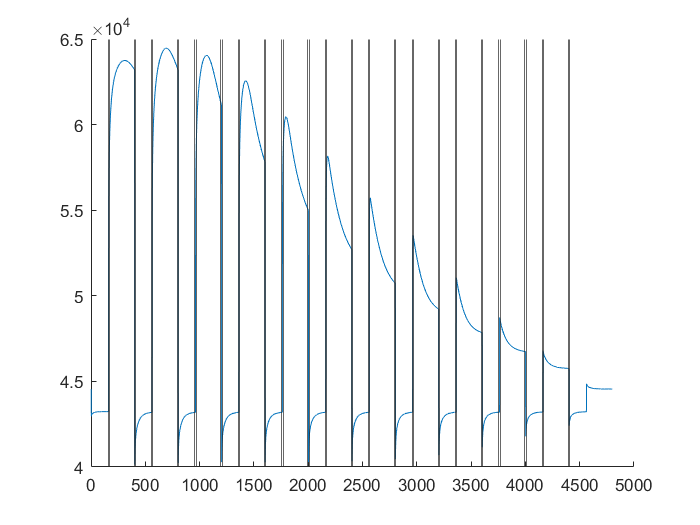

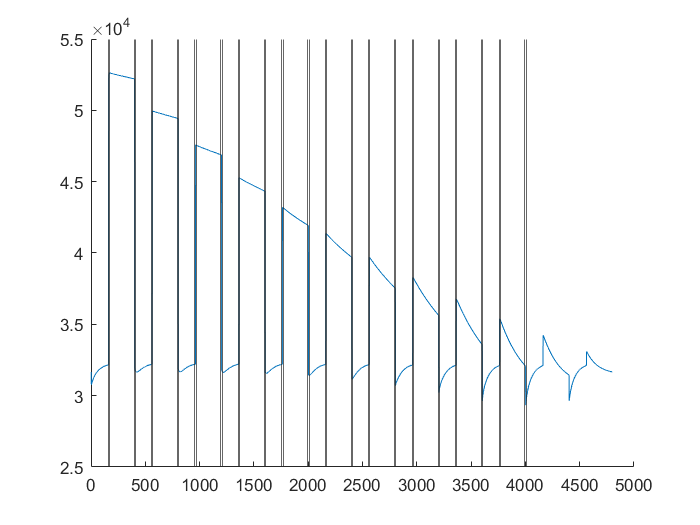

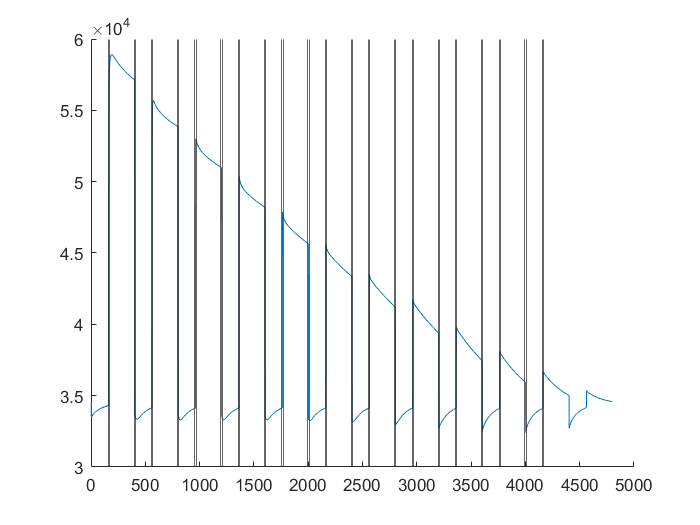

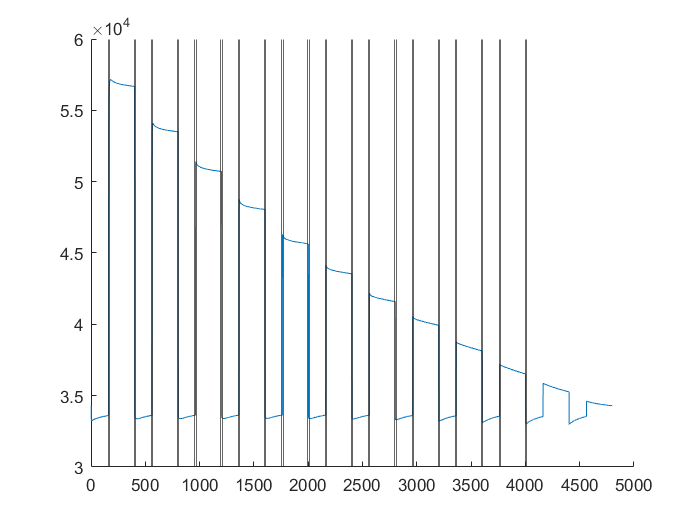

sensorsAll = cell(1,4);
sensorsAll{1,1} = sgp30_3_old(ind,:);
sensorsAll{1,2} = sgp30_2_old(ind,:);
sensorsAll{1,3} = sgp30_1_old(ind,:);
sensorsAll{1,4} = sgp30_0_old(ind,:);
for i = 1:size(stVOCE.obj{1,1}.extractors,2)
    figure()
    hold on
    plot(mean(sensorsAll{1,i},1))
    for j = 1:size(stVOCE.obj{1,1}.extractors{i}.segStart,2)
        xline(stVOCE.obj{1,1}.extractors{i}.segStart(j))
        xline(stVOCE.obj{1,1}.extractors{i}.segStop(j))
    end
end

disp("Edge")

Edge


disp(RMSE.loss(pred_oldE,targetForm_old))

   17.9997



disp("ALA")

ALA


disp(RMSE.loss(pred_oldA,targetForm_old))

   18.0475



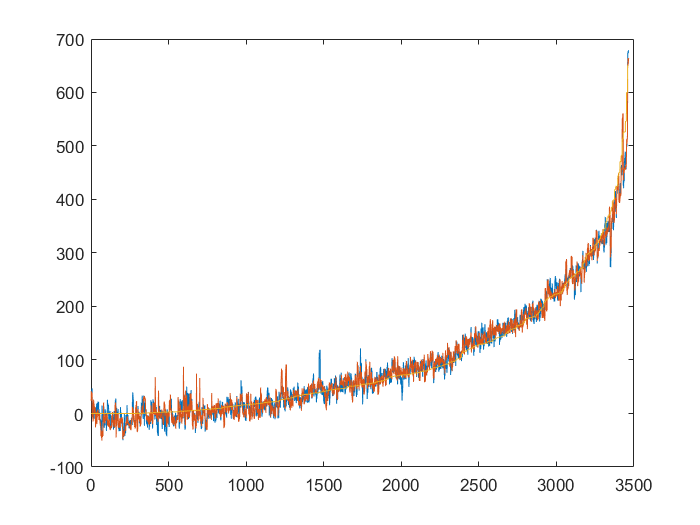


[newTarget, ind] = sort(targetForm_old);
newPredE = pred_oldE(ind);
newPredA = pred_oldA(ind);
figure()
plot(newPredE)
hold on
plot(newPredA)
plot(newTarget)